syms x1;
syms x2;
f_syms = 0.3*x1+0.1*x2+(-3.5+0.5*x1.^2+0.5*x2.^2).^2+100*x1 .* exp(-x1.^2 - x2.^2)

$$f\_syms = \frac{3\,x_{1}}{10}+\frac{x_{2}}{10}+100\,x_{1}\,{\mathrm{e}}^{-{x_{1}}^{2}-{x_{2}}^{2}}+{\left(\frac{{x_{1}}^{2}}{2}+\frac{{x_{2}}^{2}}{2}-\frac{7}{2}\right)}^{2}$$

f= @(x1, x2) 0.3*x1+0.1*x2+(-3.5+0.5*x1.^2+0.5*x2.^2).^2+100*x1 .* exp(-x1.^2 - x2.^2)

f = function_handle with value:
    @(x1,x2)0.3*x1+0.1*x2+(-3.5+0.5*x1.^2+0.5*x2.^2).^2+100*x1.*exp(-x1.^2-x2.^2)


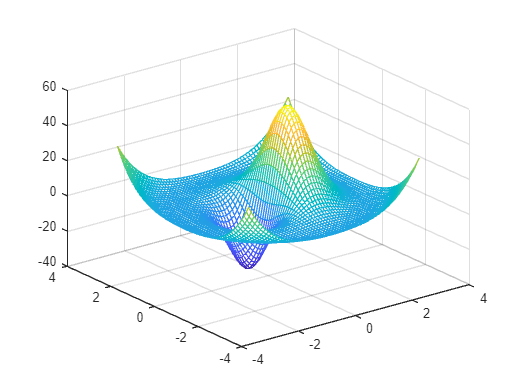


figure;
[X, Y] = meshgrid(-3:0.1:3, -3:0.1:3);
Z = f(X, Y);
mesh(X, Y, Z);

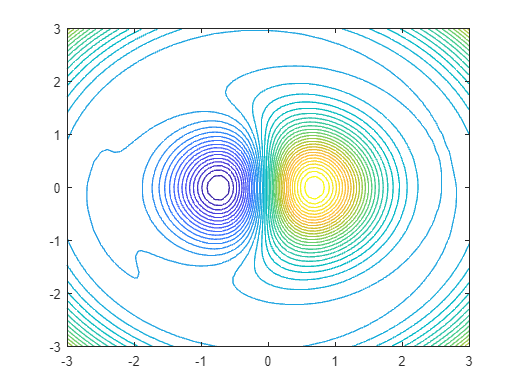

contour(X, Y, Z, 40);


n = 5;
peak = [ 0.8, 0];
pitt = [-0.8, 0];

o = f(0.8, 0)

o = 52.5358

o = f(-0.8, 0)

o = -32.3110


f = @(points) distance(points, peak, pitt);

x0 =  zeros(n, 2);
lin = linspace(peak(1), pitt(1), n+2);
x0(:, 1) = lin(:, 2:end-1);
lin = linspace(peak(2), pitt(2), n+2);
x0(:, 2) = lin(:, 2:end-1);
x0 = reshape(x0, [n * 2, 1]);

orginal = f(x0)

orginal = 84.9010


x = fminsearch(f, x0);

fmin_search = f(x)

fmin_search = 84.8625

x = reshape(x, [n,2])

x =     0.0244    0.0094
    0.0244    0.0094
   -0.0106   -0.0183
   -0.0237   -0.0075
   -0.0543    0.0224



options = optimset('Display', 'iter');

options.InitialPopulationMatrix = x0;
[x, ~] = ga(f, n*2, [], [], [], [], [], [], [], options);


Single objective optimization:
10 Variable(s)

Options:
CreationFcn:       @gacreationuniform
CrossoverFcn:      @crossoverscattered
SelectionFcn:      @selectionstochunif
MutationFcn:       @mutationgaussian

                                  Best           Mean      Stall
Generation      Func-count        f(x)           f(x)    Generations
    1              400           171.2       5.616e+05        0
    2              590           164.8       8.833e+05        0
    3              780           136.3       1.095e+06        0
    4              970           135.4       1.402e+06        0
    5             1160           120.8       1.767e+06        0
    6             1350           114.3       1.586e+06        0
    7             1540           97.89        1.36e+06        0
    8             1730           92.26       1.904e+06        0
    9             1920           92.26       1.655e+06        1
   10             2110           91.68       1.894e+06        0
   11          

ga_search = f(x)

ga_search = 85.3561

x = reshape(x, [n,2])

x =     2.1683    3.4793
    2.0456    3.4600
    0.3380    1.8095
   -0.6383    1.0607
   -0.7175    0.7026



f = @(x1, x2) 0.3*x1 + 0.1*x2 + (-3.5 + 0.5*x1.^2 + 0.5*x2.^2).^2 + 100*x1 .* exp(-x1.^2 - x2.^2);
[X, Y] = meshgrid(-3:0.1:3, -3:0.1:3);
Z = f(X, Y);
figure
mesh(X, Y, Z);

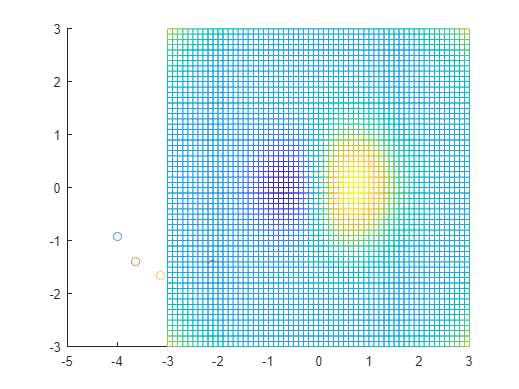

clf
figure;
f = @(x1, x2) 0.3*x1 + 0.1*x2 + (-3.5 + 0.5*x1.^2 + 0.5*x2.^2).^2 + 100*x1 .* exp(-x1.^2 - x2.^2);
[X, Y] = meshgrid(-3:0.1:3, -3:0.1:3);
Z = f(X, Y);
hold on
mesh(X, Y, Z);
for i = 2:n
    plot3(x(i, 1), x(i, 2), f(x(i, 1), x(i, 2)),'-o');
end
hold off

function [dis] = distance(points_ar, peak, pitt)
    f = @(x1, x2) 0.3*x1 + 0.1*x2 + (-3.5 + 0.5*x1.^2 + 0.5*x2.^2).^2 + 100*x1 .* exp(-x1.^2 - x2.^2);
    F = @(x) f(x(1), x(2));
    n = 5;

    points = reshape(points_ar, [n,2]);


    % Calculate the distance without penalty term
    dis = sqrt((peak(1) - points(1, 1))^2 + (peak(2) - points(1, 2))^2 + (F(peak) - F(points(1, :)))^2);
    desired_spacing = dis;
    spacing_penalty = 0;

    for i = 2:n
        last_dist = sqrt((points(i, 1) - points(i-1, 1))^2 + (points(i, 2) - points(i-1, 2))^2 + (F(points(i, :)) - F(points(i-1, :)))^2);
        dis = dis + last_dist;
        spacing_penalty = spacing_penalty + abs(last_dist - desired_spacing);
    end
    
    last_dist = sqrt((pitt(1) - points(n, 1))^2 + (pitt(2) - points(n, 2))^2 + (F(pitt) - F(points(n, :)))^2);
    dis = dis + last_dist;
    spacing_penalty = spacing_penalty + abs(last_dist - desired_spacing);
    
    
    % Adjust the weight of the penalty term based on your preference
    penalty_weight = 0; % Adjust this value based on your preference

    dis = dis + penalty_weight * spacing_penalty;
end